# Convergence study on transverse shear-locking

In this section it is shown how the rate of the mesh convergence study is reduced down due to transverse shear locking. The effect gets more pronounced with increased slenderness of the beam.

Go to [THIS](matlab:open('./main_Chapter6_HellingerReissnerFormulation_TimoshenkoBeam_Study.mlx')) Section in the main driver script *Transverse-shear locking due incompatible discretization spaces*

Go to [PREVIOUS](matlab:open('./main_Chapter61_HellingerReissnerTimoshenko_ShearForces.mlx')) Section *Transverse-shear locking due incompatible discretization spaces*

**Author: Andreas Apostolatos, PhD (aapostol@mathworks.com)**

**Date: 20.02.2023**

## Preamble

vars = ["numEl" "wEx" "X0" "XL" "choiceShapeFunctionsU" ...
    "choiceShapeFunctionsLM" "propStr" ...
    "computeBasisFunctionsAndDerivsHRU"];
str = "This mlx-file should be run from parent mlx-file " + ...
    "main_Chapter5_HellingerReissnerFormulation_TimoshenkoBeam_Study.mlx";
for ii = 1:length(vars)
    if ~exist(vars(ii), 'var') 
        error(strcat("Variable ", vars(ii), " is not defined. ", str));
    end
end

## Initialize auxiliary arrays

wAnalytical = double(wEx(XL));
tipDeflection = zeros(numEl, 5);
numElmnts = zeros(numEl, 1);
tipDeflectionAnalytical = repmat(wAnalytical, numEl, 1);

## Loop over all the refinement levels

for ii = 1:numEl

### **One-dimensional linear mesh**

    numElmnts(ii, 1) = ii; % number of elements
    mshL1Ref = generateLinearMeshOnLine(X0, XL, numElmnts(ii, 1));
    numNodesL1Ref = numel(mshL1Ref.nodes(:, 1));

### One-dimensional quadratic mesh

    mshL2Ref = generateQuadraticMeshOnLine(mshL1Ref);
    numNodesL2Ref = numel(mshL2Ref.nodes(:, 1));

### Mesh used for the discretization Lagrange Multipliers field in the frame of the Hellinger-Reissner principle

    switch choiceShapeFunctionsU
        case 1
            mshHRRef = mshL1Ref;
        case 2
            mshHRRef = mshL2Ref;
    end

### Dirichlet boundary conditions for the **one-dimensional linear mesh**

    numDOFsL1Ref = 2*numNodesL1Ref;
    freeDOFsL1Ref = 1:numDOFsL1Ref;
    homDOFsL1Ref = 1:2;
    [~, idxL1Ref] = ismember(homDOFsL1Ref, freeDOFsL1Ref);
    freeDOFsL1Ref(idxL1Ref) = [];

### Dirichlet boundary conditions for the one-dimensional quadratic mesh

    numDOFsL2Ref = 2*numNodesL2Ref;
    freeDOFsL2Ref = 1:numDOFsL2Ref;
    homDOFsL2Ref = 1:2;
    [~, idxL2Ref] = ismember(homDOFsL2Ref, freeDOFsL2Ref);
    freeDOFsL2Ref(idxL2Ref) = [];

### Number of nodes, number of DOFs and free DOFs for the Timoshenko beam formulation using the Hellinger-Reissner principle

    switch choiceShapeFunctionsU
        case 1
            numNodesHRRef = numNodesL1Ref;
            numDOFsHRRef = numDOFsL1Ref;
            freeDOFsHRRef = homDOFsL1Ref;
        case 2
            numNodesHRRef = numNodesL2Ref;
            numDOFsHRRef = numDOFsL2Ref;
            freeDOFsHRRef = freeDOFsL2Ref;
    end

### Master stiffness matrix and load vector for  the one-dimensional linear mesh using full-integration

    computeBasisFunctionsAndDerivsU = ...
        @computeLinearBasisFunctionsAndFirstDerivatives;
    computeStiffMatrixandForceVector = 'undefined';
    computeBasisFunctionsAndDerivsBeta = 'undefined';
    [KL1Ref, FBodyL1Ref] = ...
        computeMasterStiffMatrixandForceVectorTimoshenkoBeamPageWise ...
        (mshL1Ref, computeStiffMatrixandForceVector, ...
        computeBasisFunctionsAndDerivsU, computeBasisFunctionsAndDerivsBeta, ...
        propStr);
    FL1BoundaryRef = zeros(2*numNodesL1Ref, 1);
    FL1BoundaryRef(end - 1, 1) = propStr.Q;
    FL1BoundaryRef(end, 1) = propStr.M;
    FL1Ref = FBodyL1Ref + FL1BoundaryRef;

### Master stiffness matrix and load vector for the one-dimensional linear mesh using selective-reduced integration

    computeBasisFunctionsAndDerivsU = ...
        @computeLinearBasisFunctionsAndFirstDerivatives;
    computeStiffMatrixandForceVectorRI = 'undefined';
    computeBasisFunctionsAndDerivsBeta = 'undefined';
    [KL1RIRef, FBodyL1RIRef] = ...
        computeMasterStiffMatrixandForceVectorTimoshenkoBeamRIPageWise ...
        (mshL1Ref, computeStiffMatrixandForceVectorRI, ...
        computeBasisFunctionsAndDerivsU, computeBasisFunctionsAndDerivsBeta, ...
        propStr);
    FL1BoundaryRIRef = zeros(2*numNodesL1Ref, 1);
    FL1BoundaryRIRef(end - 1, 1) = propStr.Q;
    FL1BoundaryRIRef(end, 1) = propStr.M;
    FL1RIRef = FBodyL1RIRef + FL1BoundaryRIRef;

### Master stiffness matrix and load vector for the one-dimensional quadratic mesh using full-integration

    computeBasisFunctionsAndDerivsU = ...
        @computeQuadraticBasisFunctionsAndFirstDerivatives;
    computeStiffMatrixandForceVector = 'undefined';
    computeBasisFunctionsAndDerivsBeta = 'undefined';
    [KL2Ref, FBodyL2Ref] = ...
        computeMasterStiffMatrixandForceVectorTimoshenkoBeamPageWise ...
        (mshL2Ref, computeStiffMatrixandForceVector, ...
        computeBasisFunctionsAndDerivsU, computeBasisFunctionsAndDerivsBeta, ...
        propStr);
    FBoundaryL2Ref = zeros(2*numNodesL2Ref, 1);
    FBoundaryL2Ref(2*numNodesL1Ref - 1, 1) = propStr.Q;
    FBoundaryL2Ref(2*numNodesL1Ref, 1) = propStr.M;
    FL2Ref = FBodyL2Ref + FBoundaryL2Ref;

### Master stiffness matrix and load vector for the one-dimensional mesh using the Hellinger-Reissner formulation and the full-integration

    computeStiffMatrixandForceVector = ...
        @computeElStiffMtxForceVctHellingerReissnerTimoshenkoBeam;
    [KHRRef, FBodyHRRef] = computeMasterStiffMatrixandForceVectorTimoshenkoBeam ...
        (mshHRRef, computeStiffMatrixandForceVector, ...
        computeBasisFunctionsAndDerivsHRU, computeBasisFunctionsAndDerivsLM, ...
        propStr);
    FHRBoundaryRef = zeros(2*numNodesHRRef, 1);
    FHRBoundaryRef(end - 1, 1) = propStr.Q;
    FHRBoundaryRef(end, 1) = propStr.M;
    FHRRef = FBodyHRRef + FHRBoundaryRef;

### Master stiffness matrix and load vector using the Euler-Bernoulli beam theory and the cubic Hermitian basis functions

    computeStiffMatrixandForceVectorEBT = ...
        @computeElementStiffMatrixandForceVectorEulerBernoulliBeam;
    [KEBRef, FBodyEBRef] = ...
        computeMasterStiffMatrixandForceVectorEulerBernoulliBeam ...
        (mshL1Ref, computeStiffMatrixandForceVectorEBT, propStrEB);
    FBoundaryEBRef = zeros(2*numNodesL1Ref, 1);
    FBoundaryEBRef(end - 1, 1) = propStr.Q;
    FBoundaryEBRef(end, 1) = - propStr.M;
    FEBRef = FBodyEBRef + FBoundaryEBRef;

### Initialization of the solution vectors

    uL1Ref = zeros(numDOFsL1Ref, 3);
    uL2Ref = zeros(numDOFsL2Ref, 2);
    uHRRef = zeros(numDOFsHRRef, 1);

### Solution of the linear equation system corresponding to the one-dimensional linear mesh using full-integration

    uL1Ref(freeDOFsL1Ref, 1) = ...
        KL1Ref(freeDOFsL1Ref, freeDOFsL1Ref)\FL1Ref(freeDOFsL1Ref);
    tipDeflection(ii, 1) = uL1Ref(end - 1, 1);

### Solution of the linear equation system corresponding to the one-dimensional linear mesh using selective-reduced integration

    uL1Ref(freeDOFsL1Ref, 2) = ...
        KL1RIRef(freeDOFsL1Ref, freeDOFsL1Ref)\FL1RIRef(freeDOFsL1Ref);
    tipDeflection(ii, 2) = uL1Ref(end - 1, 2);

### Solution of the linear equation system corresponding to the one-dimensional quadratic mesh using full-integration

    uL2Ref(freeDOFsL2Ref, 1) = ...
        KL2Ref(freeDOFsL2Ref, freeDOFsL2Ref)\FL2Ref(freeDOFsL2Ref);
    [~, idxRef] = sort(mshL2Ref.nodes);
    wL2Ref = uL2Ref(1:2:end, 1);
    tipDeflection(ii, 3) = wL2Ref(idxRef(end), 1);

### Solution of the linear equation system corresponding to the Timoshenko Finite Element formulation using the Hellinger-Reissner principle

    uHRRef(freeDOFsL1Ref, 1) = ...
        KHRRef(freeDOFsL1Ref, freeDOFsL1Ref)\FHRRef(freeDOFsL1Ref);
    tipDeflection(ii, 4) = uHRRef(end - 1, 1);

### Solution of the linear equation system corresponding to the Euler-Bernoulli beam theory

    uL1Ref(freeDOFsL1Ref, 3) = KEBRef(freeDOFsL1Ref, freeDOFsL1Ref)\FEBRef(freeDOFsL1Ref);
    tipDeflection(ii, 5) = uL1Ref(end - 1, 3);    

end

## Plot the convergence graph

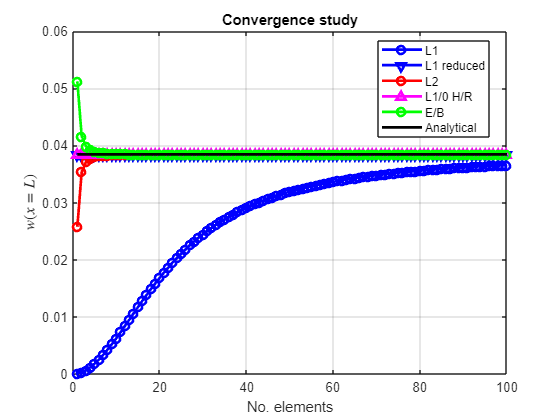

plot(numElmnts, abs(tipDeflection(:, 1)), "-bo", LineWidth=2);
hold on;
plot(numElmnts, abs(tipDeflection(:, 2)), "-bv", LineWidth=2);
plot(numElmnts, abs(tipDeflection(:, 3)), "-ro", LineWidth=2);
plot(numElmnts, abs(tipDeflection(:, 4)), "-m^", LineWidth=2);
plot(numElmnts, abs(tipDeflection(:, 5)), "-go", LineWidth=2);
plot(numElmnts, abs(tipDeflectionAnalytical), "-k", LineWidth=2);
hold off;
grid on;
legend("L1", "L1 reduced", "L2", "L" + num2str(choiceShapeFunctionsU) + ...
    '/' + num2str(choiceShapeFunctionsLM) + " H/R", "E/B", "Analytical", ...
    Location="best")
xlabel("No. elements")
ylabel("$w (x = L)$", "Interpreter","latex")
title("Convergence study")

  **Try**

Change the value of the thickness by means of the provided slider in this [code section](matlab:open('./main_Chapter6_HellingerReissnerFormulation_TimoshenkoBeam_Study.mlx')). Change its value to the extrems and the script is going to be automatically executed.

 **Reflect**

How do the convergence curves change for different values of the thickness and why?